# **ACM 11 Homework 4, Part 2: Uncertainty Quantification for the Steady Pollutant Problem**

## **Steady Pollutant Problem**: Introduction

**Motivation. **Consider a river that flows from its source at $x=0$ to $x=L$, where it flows into the ocean, with a pollutant that is being leaked into the river at a constant rate $p(x)$. 

Let $u=u(x)$ be the concentration of the pollutant at position $x$.

Due to the advection effect of the river flow, the $-a\frac{\mathrm{d} u}{\mathrm{d} x}$ term, and the diffusion effect of the pollutant, the $D\frac{\mathrm{d}^2u}{\mathrm{d}x^2}$ term, the steady state of the river is given by the PDE:

$0=-a\frac{\mathrm{d} u}{\mathrm{d} x}+D\frac{\mathrm{d}^2u}{\mathrm{d}x^2}+p(x)$**.**

where $a$ is the advection constant, and $D$ is the diffusion constant.

The boundary condition for this equation is given by $u(0)=u(L)=0$, which signifies that the concentration is 0 upstream of the river (where there is no pollutant) and at the end of the river (where the water merges into the ocean).

Here, we'll be investigating how uncertainty in the leak rate $p(x)$ influences the transport of the pollutant into the ocean.

## Warmup: Solve the Steady Pollutant Problem

In the file *solve_steady_pollutant*`.m`, we provide code to solve the steady pollutant concentration. The output of this function is two vectors: the value of $u$ on the mesh, and the value of $\frac{\mathrm{d} u}{\mathrm{d} x}$ on the mesh.

Let $a=1$ and $D=1$, and set $p(x)=1+\sin2\pi x$. By calling the function *solve_steady_pollutant*, solve the steady pollutant problem on a uniform grid with intervals of size $h=1/100$. You will use this same mesh for all later problems. Plot $u$ and $\frac{\mathrm{d} u}{\mathrm{d} x}$ in the same figure with different colors, and include appropriate axes labels, title, and legend.

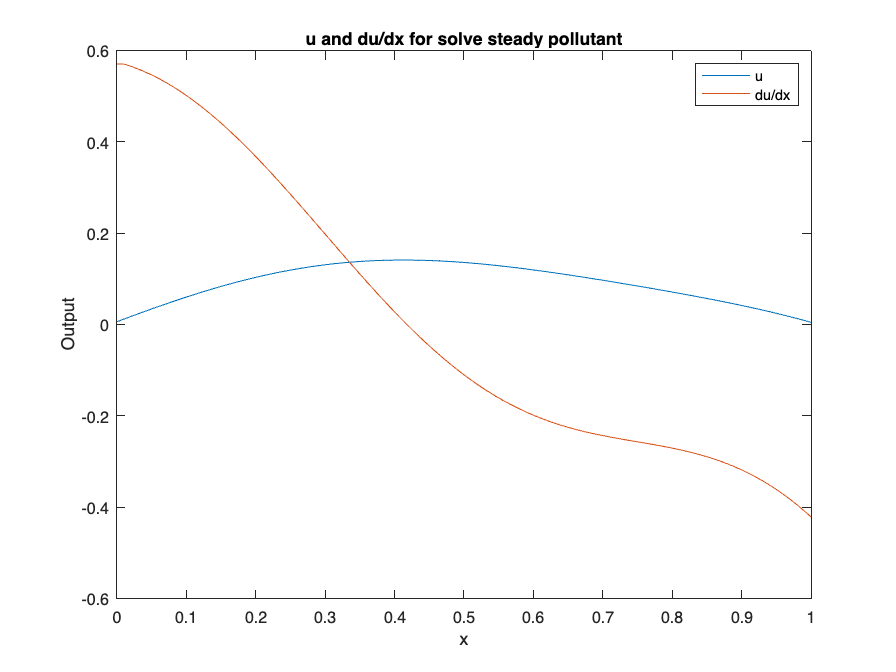

clear % always good to clear workspace before running code, so no stray variables are around to mess things up

L = 1;
a = 1;
D = 1;

x_mesh = linspace(0, L, 100);
p = @(x) 1 + sin(x* 2 * pi);
[u_mesh, ux_mesh] = solve_steady_pollutant(x_mesh,a,D,p);

figure(1); 
plot(x_mesh, u_mesh);
hold on
plot(x_mesh, ux_mesh);
title('u and du/dx for solve steady pollutant');
xlabel('x'); 
ylabel('Output'); 
legend('u','du/dx'); 

## **Problem 1: Statistics about the Pollutant Flow Rate in the Ocean **

Usually, we don't have very precise information about the leak rate $p(x)$. For example, here we assume the leak rate has a Gaussian shape

$p(x)=e^{\frac{-(x-\mu)^2}{2\sigma^2}}$,

where $\sigma\sim\mathcal{U}(0.1,0.3)$ is uniformly distributed between $0.1$ and $0.3$, and $\mu\sim\mathcal{B}(2,2)$ follows the Beta distribution with parameter $(2,2)$. Hint: You can draw samples of a beta distribution with parameter $(b_1,b_2)$ using the function `betarnd(b1,b2).`

The pollutant flow rate $q$ into the ocean is related to the derivative of $u$ at the ocean entrance: $q=-\frac{\mathrm{d} u}{\mathrm{d} x}\vert_{x=L}$. 

Let $N=1000$. Draw $N$ samples of the parameters $\left\{(\mu_k,\sigma_k)\right\}_{k=1}^N$ and use the corresponding leak rates $\left\{p_k(x)\right\}_{k=1}^N$ to solve the equation at each sample and obtain $\left\{u_k(x)\right\}_{k=1}^N$. Then collect the quantity of interest $q_k=-\frac{\mathrm{d} u_k}{\mathrm{d} x}\vert_{x=L}$ for each sample. Plot the histogram of $\left\{q_k\right\}_{k=1}^N$ and report its mean and variance. Label your histogram with appropriate axes labels and title.

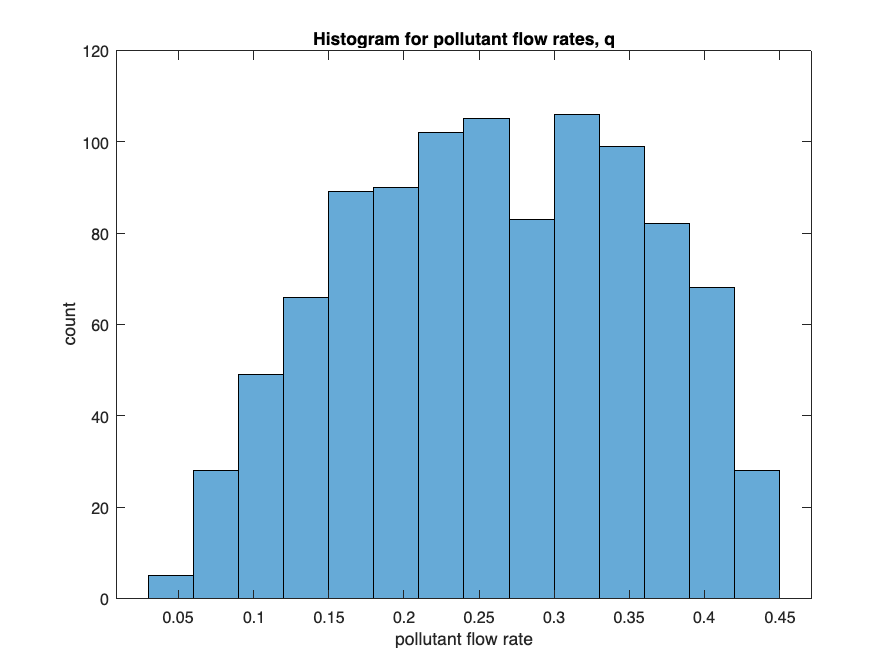

N = 1000;
q = zeros(1,N);

for k=1:N
    sigma = unifrnd(0.1, 0.3);
    mu = betarnd(2, 2);
    p = @(x) exp((-(x - mu).^2)/(2 * sigma.^2));
    
    [u_mesh, ux_mesh] = solve_steady_pollutant(x_mesh, a, D, p);
    q(k) = -ux_mesh(end);
end

figure(2); clf
histogram(q);
title('Histogram for pollutant flow rates, q');
xlabel('pollutant flow rate'); 
ylabel('count'); 



fprintf('mean: %.4f\nvariance: %.4f',mean(q),var(q))

mean: 0.2599
variance: 0.0091

## **Problem 2: Risk Estimation**

In practice, we're interested in the probability that the flow rate $q$ is larger than some threshold $C$, i.e. $\mathbb{P}[q>C]$. If this quantity is large, for example, we may need to worry about the leak and take measures to control the pollution.

We'll tackle this problem using the Monte Carlo method. Using the *N* samples of the flow rate $\left\{q_k\right\}_{k=1}^N$ generated in Problem 1, estimate the quantity $\mathbb{P}[q>C]$ as the frequency of $q_k>C$ for $k=1,\ldots, N$. Let $C=0.375$.

C = 0.375;
risk_estimate = mean(q > C);
fprintf('Monte Carlo risk estimate: %.4f',risk_estimate)

Monte Carlo risk estimate: 0.1390

## **Problem 3: Convergence of risk estimator**

Though we can obtain an estimate of $\mathbb{P}[q>C]$ using the Monte Carlo method in Problem 2, it is important to verify the accuracy of our estimate. So in this problem, we'll study the convergence of the Monte Carlo estimator.

For each $N=10, 100, 1000$, repeat the Monte Carlo method to obtain $M=100$ estimates. Then for each $N$, plot the histogram of the $100$ estimators. Use the same x-axis range for each histogram, and give each plot an appropriate title. Also compute the standard deviation of the risk estimators for each value of $N$.

**Hint: **if your computer is older or slower, with such a large $M$, the code may take several minutes to run. To make it time-saving for debugging, start with a small $M$ (like $3\sim 5$). You may also be interested in experimenting with **parfor** (parallel for loop) for the inner-most loop. When you are certain that your code is bug-free, use the original large $M$ and run the code while taking a tea/coffee break!

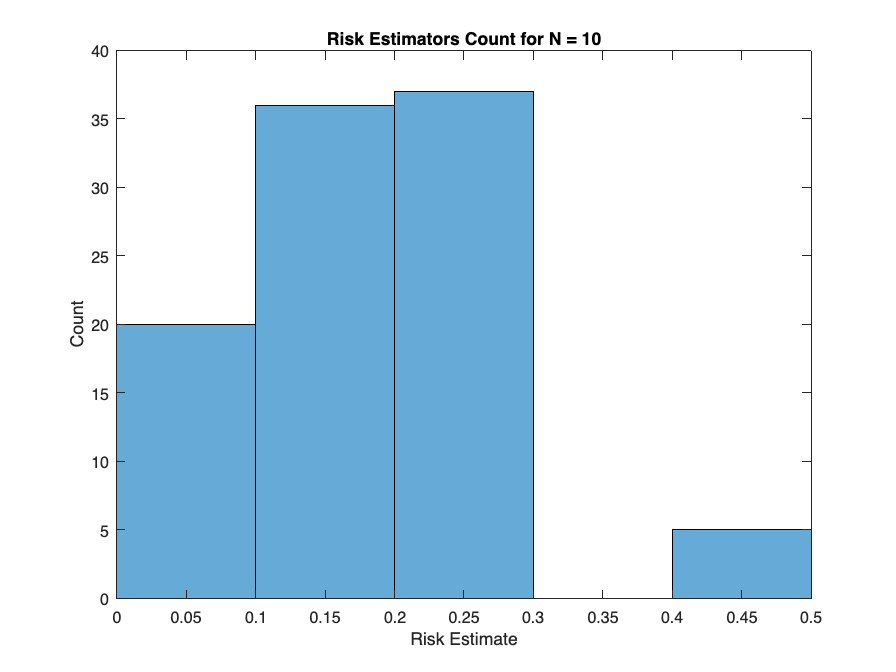

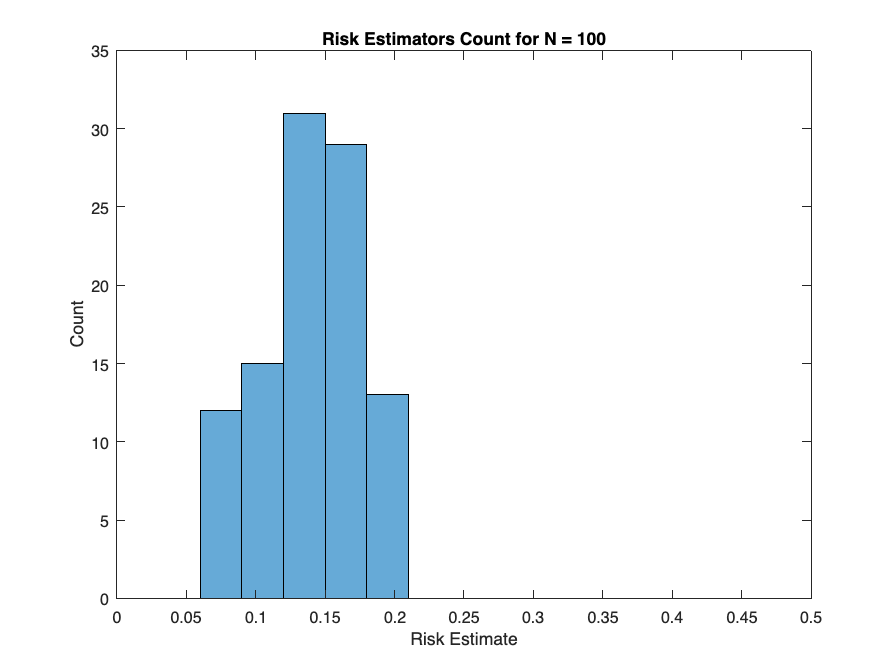

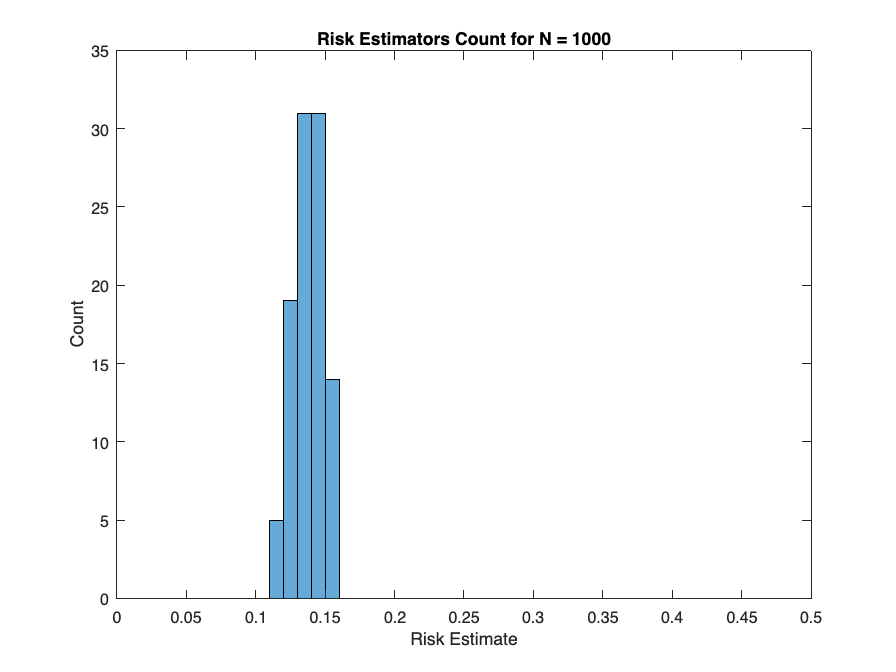

C = 0.375;
N_list = [10, 100, 1000];
M = 100;
lN = length(N_list);
risk_estimator = zeros(lN, M);
estimator_spread = zeros(lN,1);

for i = 1:lN
    n = N_list(i);
    for m=1:M
        q = zeros(1,n);
        % same methods as prev problems
        for k=1:n
            sigma = unifrnd(0.1, 0.3);
            mu = betarnd(2, 2);
            p = @(x) exp((-(x - mu).^2)/(2 * sigma.^2));
    
            [u_mesh, ux_mesh] = solve_steady_pollutant(x_mesh, a, D, p);
            q(k) = -ux_mesh(end);
        end
        risk_estimate = 0;
        for k = 1:n
            if (q(k) > C)
                risk_estimate = risk_estimate + 1;
            end
        end
        risk_estimator(i,m) = risk_estimate/n;
    end
    figure(2+i); clf;
    histogram(risk_estimator(i,:));
    xlim([0 0.5]);
    title("Risk Estimators Count for N = " + n);
    xlabel('Risk Estimate'); 
    ylabel('Count'); 
     
    % calculate and store standard deviation of risk estimator
    estimator_spread(i,1) = std(risk_estimator(i,:));
    
end

The number of samples we use to compute a single risk estimate is $N$. How does this required number of samples change if we want the estimator spread (as measured by estimator standard deviation) to decrease by a factor of 10?

If we want the estimator standard deviation to decrease by a factor of 10, we must increase N by 10^2. This can be seen by printing estimator spread for each N (done below). Comparing N = 10 vs N = 1000, N = 1000 has a standard deviation of 10x less than N= 10.

estimator_spread

estimator_spread =     0.1259
    0.0335
    0.0110


**Problem 4: How many hours did you spend on this MATLAB part of the homework?**

hours = 2

hours = 2